# Augmenting Data with Different Levels of Focus -Only ML

## Load Data

clear
clc

VONNPath = pwd;
CS670Path = fullfile(VONNPath, "Patrick Do/CS670");

dataOpt = "AVOData_Psy_80Train_20Test_V1R3S_Train_50PerClass";

% Load train and test data
imdsTrain = imageDatastore(fullfile(CS670Path, "Data_CS670", dataOpt), ...
    "IncludeSubfolders",true, "LabelSource","foldernames", "FileExtensions",".mat", "ReadFcn",@loadPD);

valDataOpt = "AVOData_Psy_80Train_20Test_V1R3S_Test_175PerClass";
imdsVal = imageDatastore(fullfile(CS670Path, "Data_CS670", valDataOpt), ...
    "IncludeSubfolders",true, "LabelSource","foldernames", "FileExtensions",".mat", "ReadFcn",@loadPD);

% Load importance score
load(fullfile(CS670Path, "Augmented_Data_V1_CS670/", dataOpt , "importanceScore.mat"));

## Augmenting Enhanced Images with Spatial Attention

% Load ATLAS
load(fullfile(VONNPath, 'CollaboratingProjects/AVOProject/Report/March25_26_All','imMask.mat'));
numROI = 95;

sigRoiFreq = zeros(1,95);
for t = 1:length(imdsTrain.Files)
    a = getRoiWeightsWithThres(LIME_scores_train(t,:), 1);
    sigRoiFreq = sigRoiFreq + a;
end

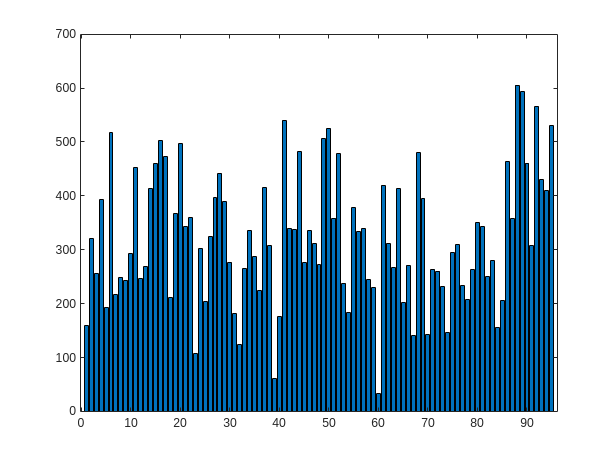

figure;
bar(sigRoiFreq)

[~, sigROI] = maxk(sigRoiFreq, 20);

sortedSigROI = sort(sigROI)

sortedSigROI =      6    11    15    16    17    20    28    41    44    49    50    52    68    86    88    89    90    92    93    95


importantROIs = [35,36, 57,58, 61,62, 67,68, 85,86, 89,90, 91,92, 94,95];

intersect(importantROIs, sigROI)

ans =     68    86    89    90    92    95


knownImportanceMasks = zeros(numROI,1);
importantROIs = [35,36, 57,58, 61,62, 67,68, 85,86, 89,90, 91,92, 94,95];
knownImportanceMasks(importantROIs) = 1;

#### Compute Important Scores of ROIs using SHAP and LIME

numImg = length(imdsTrain.Files);

for k=1:numImg
    % Orginal image and its labels
    X = readimage(imdsTrain, k);
    label = char(imdsTrain.Labels(k));

    for importanceThres = 0.5:0.25:1
        [~, importanceMasks] = getRoiWeightsWithThres(LIME_scores_train(k,:), importanceThres);
        % importanceMasks = importanceMasks & knownImportanceMasks;

        % Compute guided map 
        guidedMap = zeros(size(imMask));
        for ROI_thr = 1:numROI
            if (importanceMasks(ROI_thr) == 1)
                ROI_ind = find(imMask == ROI_thr);
                guidedMap(ROI_ind) = 1;
            end
        end

        for weight = 0.1:0.1:1
            % Enhance image with guided map
            % enhanced image = original image + (weight * guidedMap) .* orginal image
            enhancedImage = X + (weight * guidedMap) .* X;

            % Create folder for saving data
            enhancedImageFolder = fullfile(CS670Path, "Augmented_Data_V1_CS670", dataOpt, ...
                strcat("weight_", num2str(weight), "_importanceThres_", num2str(importanceThres)), "Train", label);
            if ~exist(enhancedImageFolder, "dir")
                mkdir(enhancedImageFolder);
            end

            % Save enhanced image and guided map
            [filepath, filename, ext] = fileparts(imdsTrain.Files(k));
            save(fullfile(enhancedImageFolder, strcat(filename, ".mat")), "enhancedImage", "guidedMap")
        end
    end
end

#### Test Set

numImg = length(imdsVal.Files);

for k=1:numImg
    % Orginal image and its labels
    X = readimage(imdsVal, k);
    label = char(imdsVal.Labels(k));

    for importanceThres = 0.5:0.25:1
        [~, importanceMasks] = getRoiWeightsWithThres(LIME_scores_test(k,:), importanceThres);
        % importanceMasks = importanceMasks & knownImportanceMasks;

        % Compute guided map 
        guidedMap = zeros(size(imMask));
        for  ROI_thr = 1:numROI
            if (importanceMasks(ROI_thr) == 1)
                ROI_ind = find(imMask == ROI_thr);
                guidedMap(ROI_ind) = 1;
            end
        end

        for weight = 0.1:0.1:1
            % Enhance image with guided map
            % enhanced image = original image + (weight * guidedMap) .* orginal image
            enhancedImage = X + (weight * guidedMap) .* X;

            % Create folder for saving data
            enhancedImageFolder = fullfile(CS670Path, "Augmented_Data_V1_CS670", dataOpt, ...
                strcat("weight_", num2str(weight), "_importanceThres_", num2str(importanceThres)), "Test", label);
            if ~exist(enhancedImageFolder, "dir")
                mkdir(enhancedImageFolder);
            end

            % Save enhanced image and guided map
            [filepath, filename, ext] = fileparts(imdsVal.Files(k));
            save(fullfile(enhancedImageFolder, strcat(filename, ".mat")), "enhancedImage", "guidedMap")
        end
    end
end

## Functions

function importanceScores = getROIweights(scores)
    [numSubjects, numFeatures] = size(scores);
    importanceScores = zeros(numSubjects, numFeatures);
    
    for k = 1:numSubjects
        scoresAbs = abs(scores(k,:));
        meanScore = mean(scoresAbs);
        stdScore = std(scoresAbs);

        % Set values below the threshold to 0
        threshold = meanScore + stdScore;
        scoresAbs(scoresAbs < threshold) = 0;

        importanceScores(k,:) = scoresAbs;
    end
end

function [importanceScores, importanceMasks] = getRoiWeightsWithThres(scores, thres)
    scoresAbs = abs(scores);
    meanScore = mean(scoresAbs);
    stdScore = std(scoresAbs);

    % Set values below the threshold to 0
    threshold = meanScore + thres*stdScore;
    scoresAbs(scoresAbs < threshold) = 0;

    importanceScores = scoresAbs;
    importanceMasks = importanceScores > 0;
end
